% ECG Signal Generation and Processing
clear; clc;

addpath 'ecg_simulation/';
addpath 'generate_signals/';
addpath 'generate_LUTs/';

% Parameters
BPM = 72;
peak = 0.5;
Ns = 128;
RES = 12;
fs = 4000;
t = linspace(0, 60/BPM, Ns);

% Generate clean ECG
clean_ecg = generate_clean_ecg(BPM, peak, Ns);

a = 0.0175

u1 = 2.4000

u2 = 0


% Add noise
noisy_ecg = add_noise(clean_ecg, peak, fs, t);

% Filter the noisy ECG
filtered_ecg = filter_ecg(noisy_ecg, fs);

% Generate LUTs
clean_lut = generate_lut(clean_ecg, RES);
noisy_lut = generate_lut(noisy_ecg, RES);
filtered_lut = generate_lut(filtered_ecg, RES);

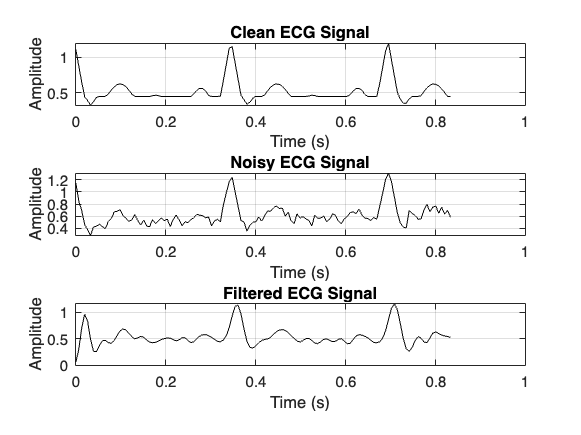

% Plot all signals
figure('Position', [100, 100, 800, 600]);

subplot(3,1,1)
plot(t, clean_ecg, 'k')
grid on
title('Clean ECG Signal')
xlabel('Time (s)')
ylabel('Amplitude')

subplot(3,1,2)
plot(t, noisy_ecg, 'k')
grid on
title('Noisy ECG Signal')
xlabel('Time (s)')
ylabel('Amplitude')

subplot(3,1,3)
plot(t, filtered_ecg, 'k')
grid on
title('Filtered ECG Signal')
xlabel('Time (s)')
ylabel('Amplitude')

% save with higher resolution
print('figures/ecg_signals_hires', '-dpng', '-r300')  % 300 DPI resolution

% Save LUTs to files
save_lut_to_file(clean_lut, 'LUTs/clean_ecg_lut.txt');
save_lut_to_file(noisy_lut, 'LUTs/noisy_ecg_lut.txt');
save_lut_to_file(filtered_lut, 'LUTs/filtered_ecg_lut.txt');